Geometria

%%
%Geometry Subsystem
A = readmatrix('data\X[mm]_alfa[deg].txt');
X = A(:,1) / 1000; %[m]
RAD = deg2rad(A(:,2)); %[rad]

Dynamika

%Dynamics Subsystem
velocity = 0:1:832/3.6; % [m/s]
velocity = transpose(velocity);

angles = deg2rad(-15):deg2rad(0.5):deg2rad(15);
C_x = 1.0835.*angles.^2 - 0.0242.*angles + 0.0079; % [-]
C_z = 4.6162.*angles - 0.0095; %[-]


%Wyliczenie wartosci kata beta potrzebnego do wylicznia siły
beta_angles = angles;
angles = rad2deg(angles);
x = 900 -0.0004*angles.^3 + 0.015*angles.^2 + 4.6075.*angles - 0.027;
angles = deg2rad (angles);
for i =1:length(angles)
    fun = @(b) cos(angles(i)) * 225 + sin(angles(i))*125 - sin(b)*x(i) - cos(b)*225;
    beta_angles(i) = fsolve(fun,0);
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 


%Wartosci geometryczne płata
cord = 0.84; % [m]
S = 5.22; % [m^2]
rho = 0.38877; % [kg/m^3] for 10670 m
F_aero = sqrt((0.5 * rho.*velocity.^2 * S.*C_x).^2+(0.5*rho.*velocity.^2 * S.*C_z.^2));
for i = 1:length(C_z)
    if C_z(i)<0
        F_aero(:,i) = -1.*F_aero(:,i);
    end
end
 %[N]

F_force = F_aero.*(0.15 + 0.25 * cord + (x/1000).*cos(angles - beta_angles))/0.225; %[N]

Siłownik

%Actuator Subsystem
size = 1;
A_1 = (pi * (1.2 * 15)^2) / 4 / 10000 * size^2;     % [m^2]
A_2 = (pi * ((1.2 * 15)^2-(1.2*5)^2)) / 4 / 10000 * size^2;     % [m^2]
V_01 = A_1 * (174 * 1.2/2 - 10 - 5)/100 * size;   % [m^3]
V_02 = A_2 * (174 * 1.2/2 - 10 - 5)/100 * size;  % [m^3]
m = 8 * 10^(-6) * pi/4 * (5 * 1.2)^2 * 200 * size^3;           % [kg]
K = 1.44 *10^9;    % [Pa]
p_0 = 102400; %[Pa]
x_max = 0.07;          % [m] maksymalne wychylenie
x_min = -0.07;          % [m] minimalne wychylenie

Sensor

% Sensor Subsystem
filter_coef = 0.0000000002;

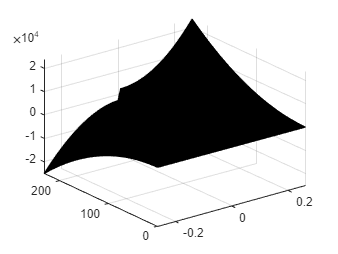

surf(angles,velocity,F_force);